
clc;
clear all;
close all;
tic

## generate data

run ("Basics.m")

sys =
 
                 1.3 s + 1.333
  --------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



fb = 2.4327

sysd =
 
  0.0004236 z^3 + 0.001167 z^2 - 0.000997 z - 0.0003069
  -----------------------------------------------------
      z^4 - 3.481 z^3 + 4.58 z^2 - 2.697 z + 0.5991
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



c =          0    0.0004    0.0012   -0.0010   -0.0003


d =     1.0000   -3.4807    4.5802   -2.6968    0.5991


tfinal=200;
t = 0:T_s:tfinal;
u = zeros(numel(t),1);

#### General Input+white Noise

% u = gensig('sine' , tfinal , tfinal ,T_s);
% Noise=-0.2+(0.2+0.2)*rand(numel(t),1);
% u=u+Noise;

#### 1.Pulse Input

% u(1:50,1)=ones(50,1) ;

#### 2.Step Input

% u=ones(numel(t),1);
% % u(round(numel(t)/10,0):end,1)=1;

#### 3.Sine Input

% u = gensig('sine' , tfinal/15 , tfinal ,T_s);

#### 4.Ramp Input

for i=1:numel(t)
    u(i)= 1.2*i;%randi(1);
end    

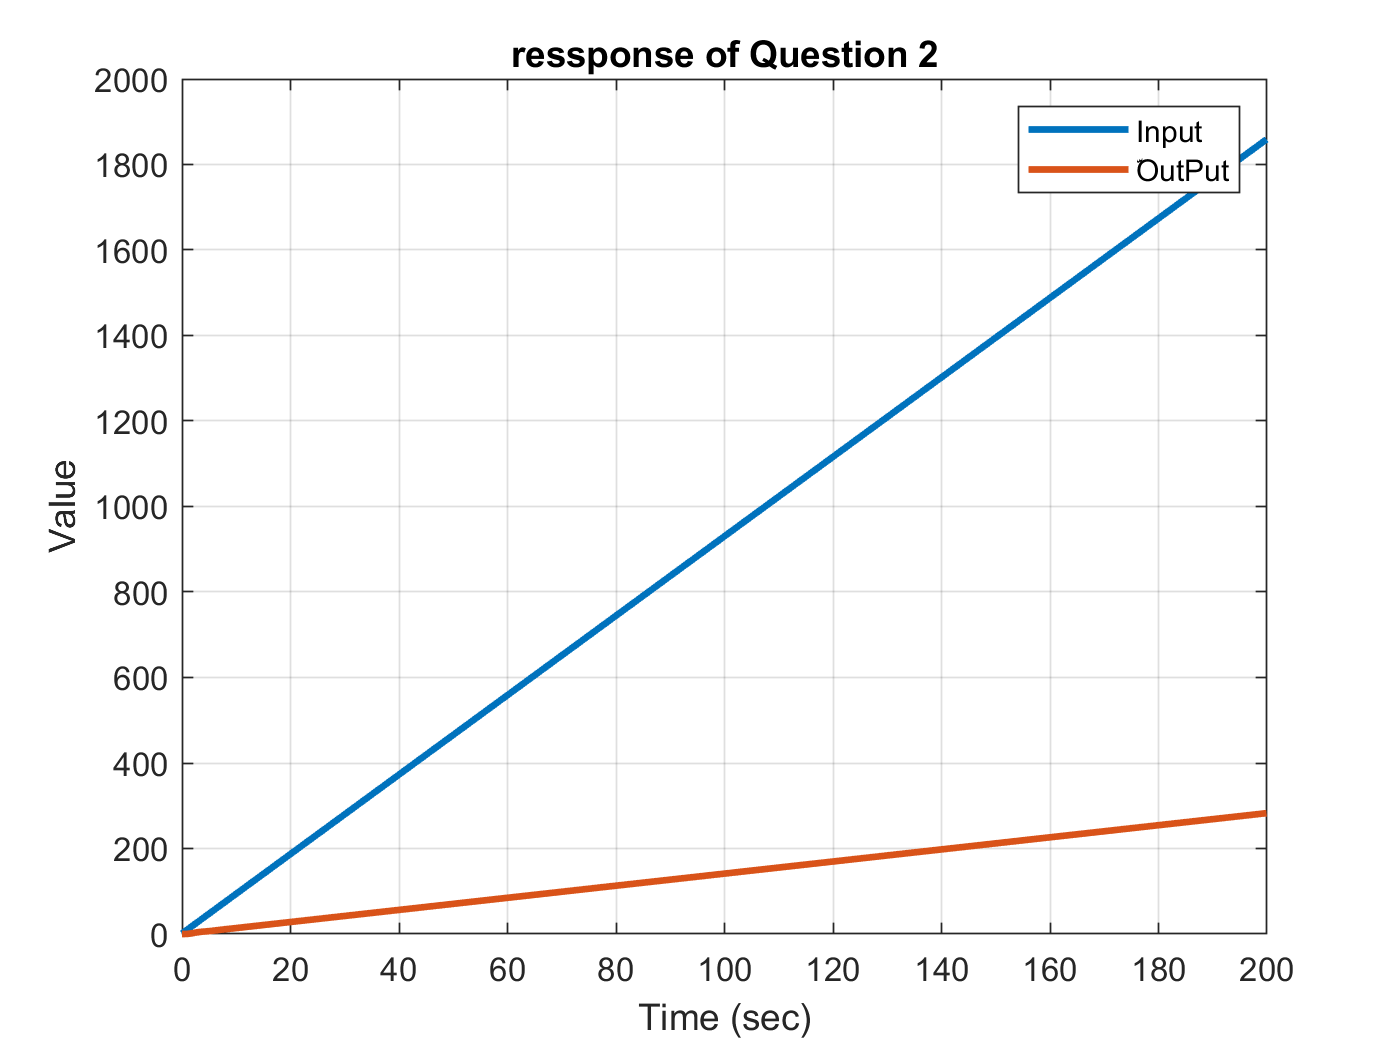

y = lsim(sysd  ,u ,t);
plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;

## Recursive Least Square estimation

N = numel(y) ;
%choose number of parameters
Parameters_in_den=4

Parameters_in_den = 4

Parameters_in_num=4

Parameters_in_num = 4

Nv=Parameters_in_num+Parameters_in_den

Nv = 8

theta(:,1:Nv) = zeros(Nv , Nv) ;
P = 1e12*eye(Nv) ;
phi=[];

Eror=zeros(1,N);
for i = (max(Parameters_in_num,Parameters_in_den)+1):N
    phi(:,i) = [(y(i-1:-1:i-Parameters_in_den))' , (u(i-1:-1:i-Parameters_in_num))']';
    K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;
    P = (eye(Nv) - K*phi(:,i)')*P ;
    theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1)); 
    Eror(i)=(Eror(i-1)+(y(i)-phi(:,i)'*theta(:,i))^2);
end


### ‌BODE

ident_dis = tf(theta((Parameters_in_num+1):end,end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s)

ident_dis =
 
  0.0007227 z^3 + 0.0002826 z^2 - 0.0001577 z - 0.0005981
  -------------------------------------------------------
       z^4 - 3.495 z^3 + 4.616 z^2 - 2.726 z + 0.607
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
  0.002924 s^3 + 0.001001 s^2 + 1.307 s + 1.152
  ---------------------------------------------
  s^4 + 3.865 s^3 + 7.894 s^2 + 10.39 s + 7.566
 
Continuous-time transfer function.



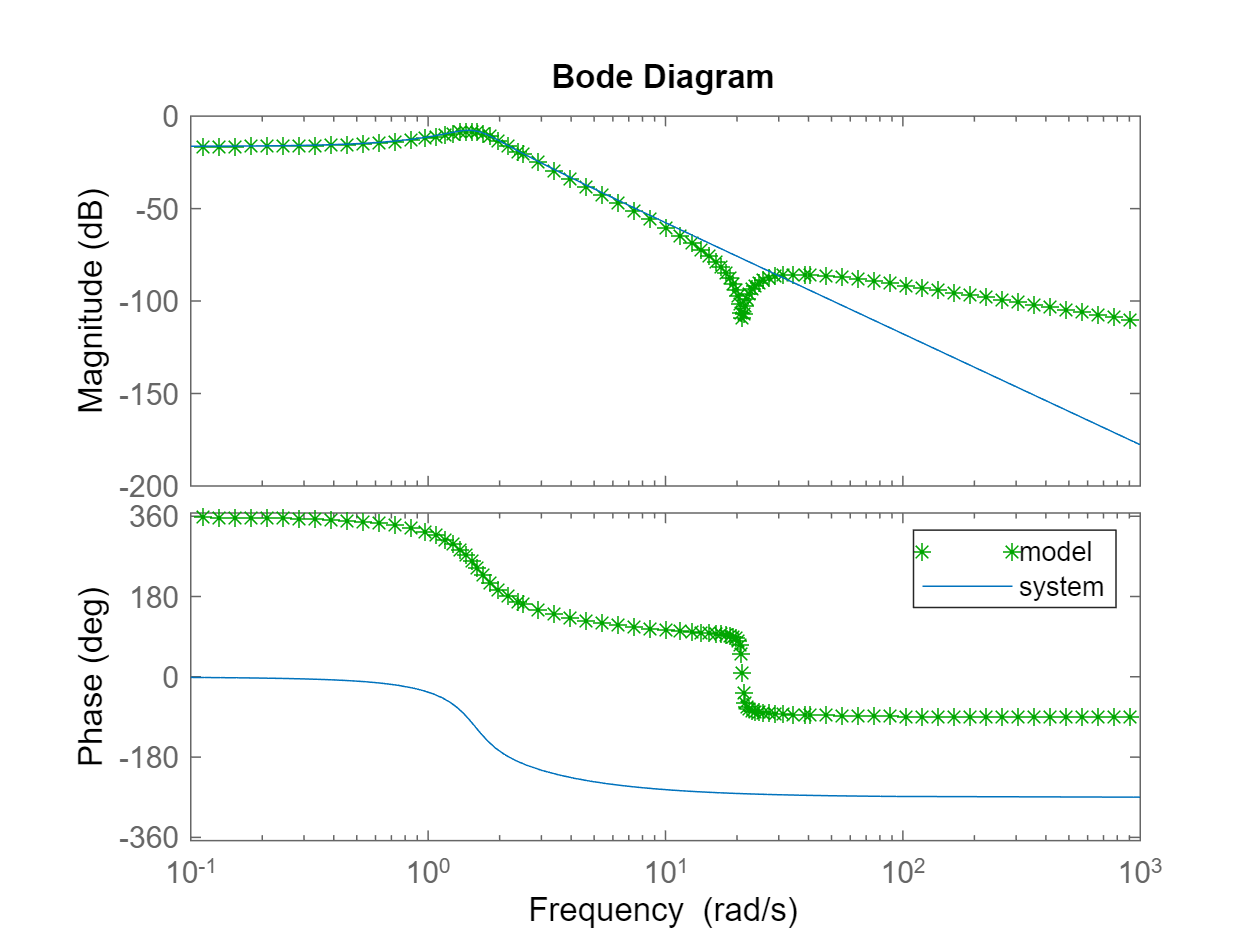

bode(ident_analog ,'g*',sys)
legend('model ','system')

RLS Convergence

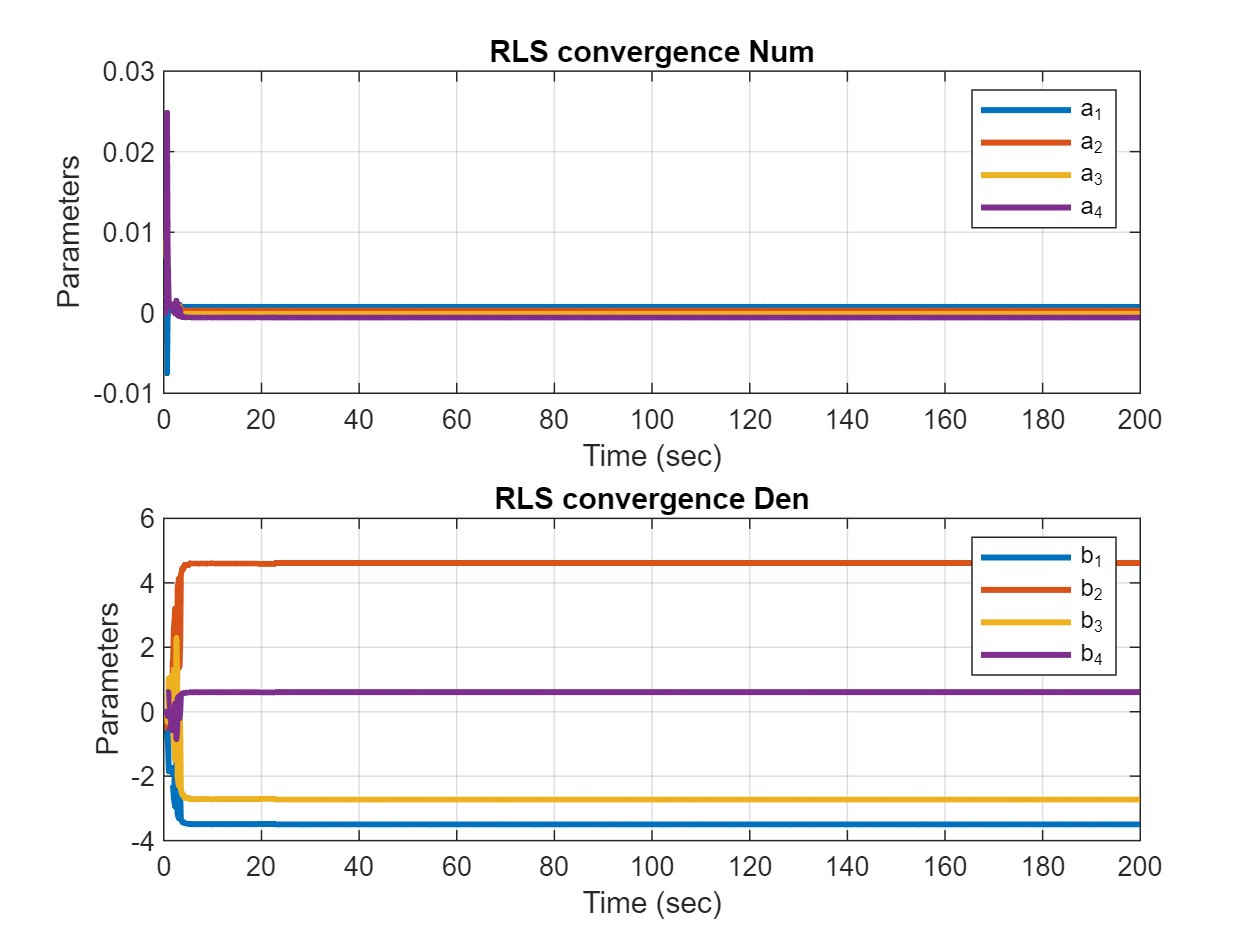

subplot(2,1,1)
plot(t , theta((Parameters_in_num+1):end,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence Num') ;
grid on
legend('a_1','a_2','a_3','a_4')
% xlim([0 6])
% ylim([-0.5 0.5])
%--------------------------------------------------------------
subplot(2,1,2)
plot(t , -theta(1:Parameters_in_num ,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence Den') ;
grid on
legend('b_1','b_2','b_3','b_4')

% xlim([0 6])
% ylim([-2 2])

### Ploting discret system and Least square Model via step input

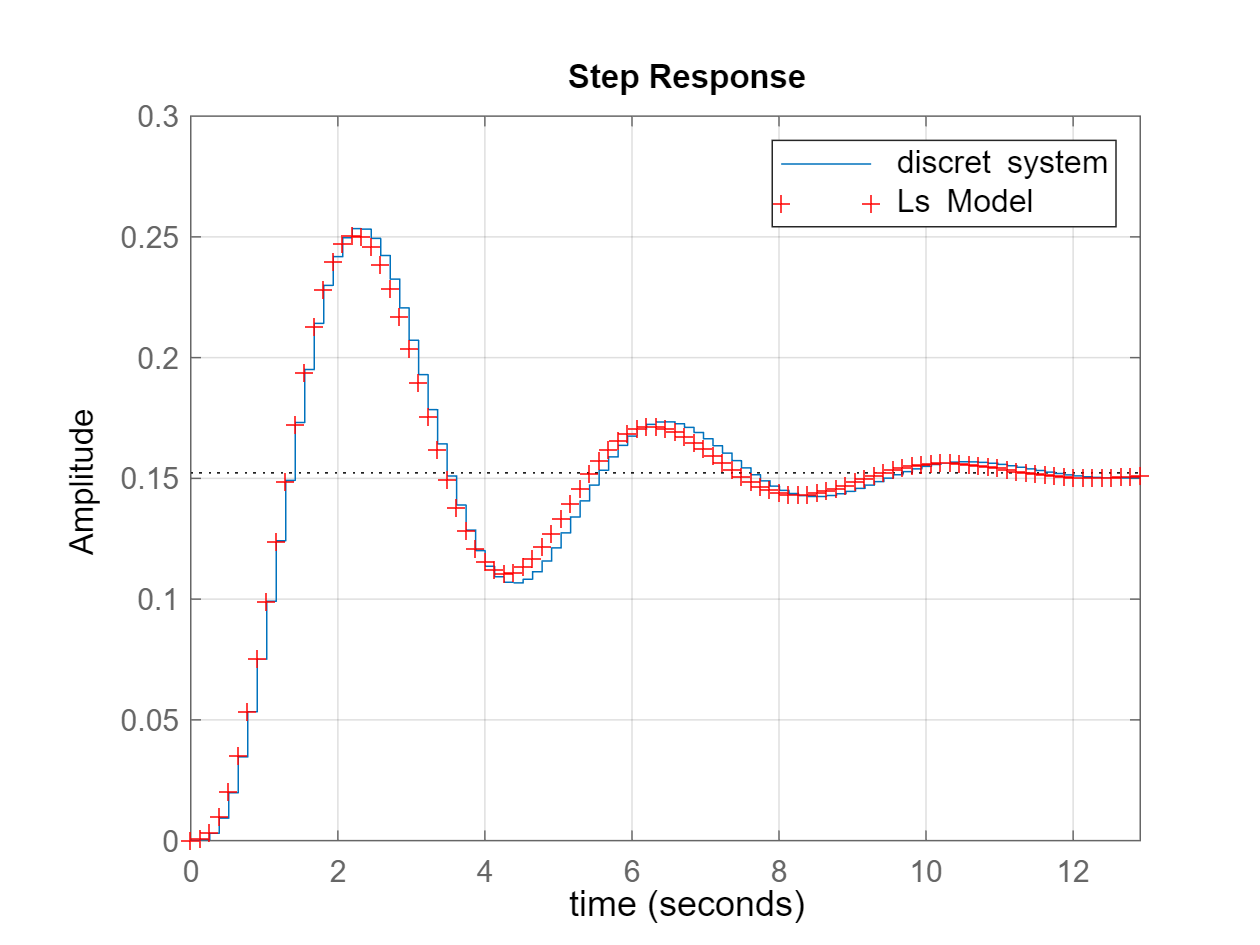

figure
step(sysd,0:T_s:100*T_s)
hold on
step(ident_analog,0:T_s:100*T_s,'r+')
legend('\fontsize{12} discret system','\fontsize{12} Ls Model');
grid on;
xlabel('time','fontsize',12);

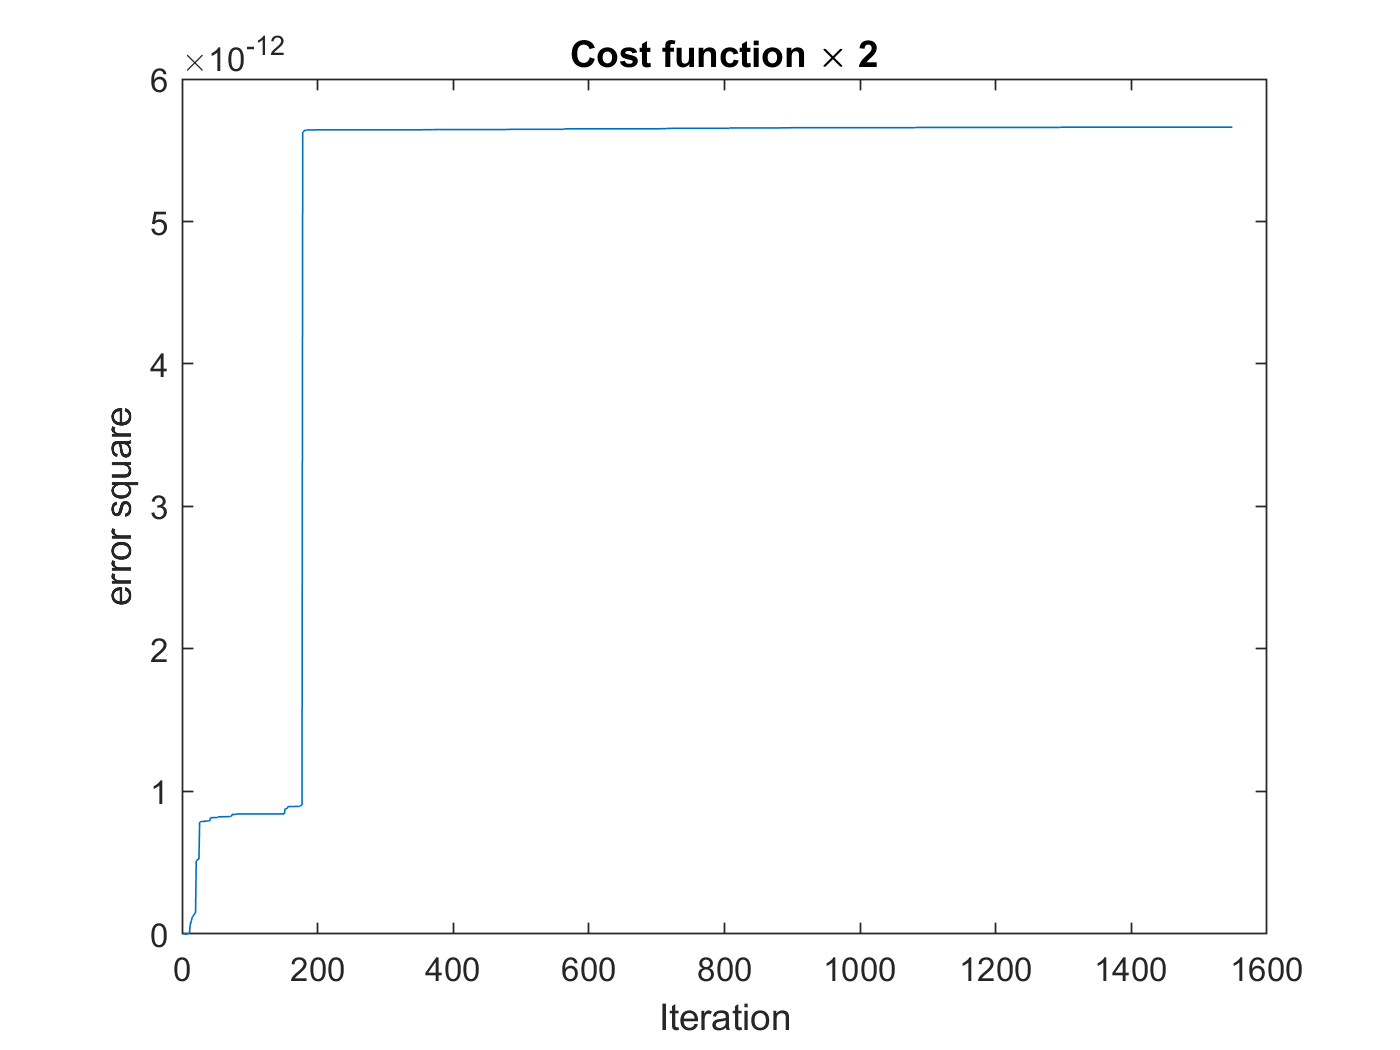

figure
plot(Eror)
xlabel('Iteration') ;
ylabel('error square') ;
title('Cost function \times 2') ;


toc

Elapsed time is 10.216477 seconds.
